clear
syms L_i L_t L_h
assume(L_i,'positive')
assume(L_t,'positive')
assume(L_h,'positive')
syms x y theta_t phi
assume(x,'real')
assume(y,'real')
assume(theta_t,'real')
assume(phi,'real')
syms v delta_t delta_i
assume(v,'real')
assume(delta_t,'real')
assume(delta_i,'real')

x_dot = v*cos(theta_t)

$$x\_dot = v\,\cos\left(\theta_{t}\right)$$

y_dot = v*sin(theta_t)

$$y\_dot = v\,\sin\left(\theta_{t}\right)$$


r1 = (L_t / tan(delta_t))

$$r1 = \frac{L_{t}}{\tan\left(\delta_{t}\right)}$$

r2 = sqrt(r1^2+L_h^2)

$$r2 = \sqrt{\frac{{L_{t}}^{2}}{{\tan\left(\delta_{t}\right)}^{2}}+{L_{h}}^{2}}$$

% alpha1 = atan2(L_h, r1)
alpha1 = atan(L_h/r1)

$$alpha1 = \mathrm{atan}\left(\frac{L_{h}\,\tan\left(\delta_{t}\right)}{L_{t}}\right)$$

alpha4 = alpha1 + phi + delta_i

$$alpha4 = \delta_{i}+\varphi +\mathrm{atan}\left(\frac{L_{h}\,\tan\left(\delta_{t}\right)}{L_{t}}\right)$$

r3 = L_i * cos(delta_i) / sin(alpha4)

$$r3 = \frac{L_{i}\,\cos\left(\delta_{i}\right)}{\sin\left(\delta_{i}+\varphi +\mathrm{atan}\left(\frac{L_{h}\,\tan\left(\delta_{t}\right)}{L_{t}}\right)\right)}$$

theta_t_dot = v / r1

$$theta\_t\_dot = \frac{v\,\tan\left(\delta_{t}\right)}{L_{t}}$$

% vh = (theta_t_dot) * r2

vh = v*sqrt(1+L_h^2*tan(delta_t)^2/L_t^2)

$$vh = v\,\sqrt{\frac{{L_{h}}^{2}\,{\tan\left(\delta_{t}\right)}^{2}}{{L_{t}}^{2}}+1}$$


% vh = simplify(vh,'IgnoreAnalyticConstraints',true)
theta_i_dot = - vh / r3

$$theta\_i\_dot = -\frac{v\,\sin\left(\delta_{i}+\varphi +\mathrm{atan}\left(\frac{L_{h}\,\tan\left(\delta_{t}\right)}{L_{t}}\right)\right)\,\sqrt{\frac{{L_{h}}^{2}\,{\tan\left(\delta_{t}\right)}^{2}}{{L_{t}}^{2}}+1}}{L_{i}\,\cos\left(\delta_{i}\right)}$$

phi_dot = theta_i_dot - theta_t_dot

$$phi\_dot = -\frac{v\,\tan\left(\delta_{t}\right)}{L_{t}}-\frac{v\,\sin\left(\delta_{i}+\varphi +\mathrm{atan}\left(\frac{L_{h}\,\tan\left(\delta_{t}\right)}{L_{t}}\right)\right)\,\sqrt{\frac{{L_{h}}^{2}\,{\tan\left(\delta_{t}\right)}^{2}}{{L_{t}}^{2}}+1}}{L_{i}\,\cos\left(\delta_{i}\right)}$$


r1 = L_t / tan(delta_t);
r2 = sqrt(r1^2+L_h^2);
r3 = L_i * cos(delta_i) / sin(atan(L_h/r1) + phi + delta_i);
theta_t_dot = (v / r1);
vh = (theta_t_dot) * r2;
if isnan(vh)
    vh = v;
end
theta_i_dot = -(vh / r3);
phi_dot2 = theta_i_dot - theta_t_dot;

c1 = v/L_i*sqrt(1+(L_h^2/L_t^2)*(tan(delta_t))^2);

$$c1 = \frac{v\,\sqrt{\frac{{L_{h}}^{2}\,{\tan\left(\delta_{t}\right)}^{2}}{{L_{t}}^{2}}+1}}{L_{i}}$$

c2 = atan((L_h/L_t)*tan(delta_t)) + phi;

$$c2 = \varphi +\mathrm{atan}\left(\frac{L_{h}\,\tan\left(\delta_{t}\right)}{L_{t}}\right)$$

c3 = (v/L_t)*tan(delta_t);

$$c3 = \frac{v\,\tan\left(\delta_{t}\right)}{L_{t}}$$

phi_dot3 = -c1.*sin(c2 + delta_i)./cos(delta_i)-c3

$$phi\_dot3 = -\frac{v\,\tan\left(\delta_{t}\right)}{L_{t}}-\frac{v\,\sin\left(\delta_{i}+\varphi +\mathrm{atan}\left(\frac{L_{h}\,\tan\left(\delta_{t}\right)}{L_{t}}\right)\right)\,\sqrt{\frac{{L_{h}}^{2}\,{\tan\left(\delta_{t}\right)}^{2}}{{L_{t}}^{2}}+1}}{L_{i}\,\cos\left(\delta_{i}\right)}$$


c1 = v/L_i*sqrt(1+L_h^2/L_t^2*tan(delta_t)^2);
c2 = atan(L_h/L_t*tan(delta_t)) + phi;
c3 = v/L_t*tan(delta_t);
phi_dot4 = -c1.*sin(c2 + delta_i)./cos(delta_i)-c3

$$phi\_dot4 = -\frac{v\,\tan\left(\delta_{t}\right)}{L_{t}}-\frac{v\,\sin\left(\delta_{i}+\varphi +\mathrm{atan}\left(\frac{L_{h}\,\tan\left(\delta_{t}\right)}{L_{t}}\right)\right)\,\sqrt{\frac{{L_{h}}^{2}\,{\tan\left(\delta_{t}\right)}^{2}}{{L_{t}}^{2}}+1}}{L_{i}\,\cos\left(\delta_{i}\right)}$$

## Plotting the variable space

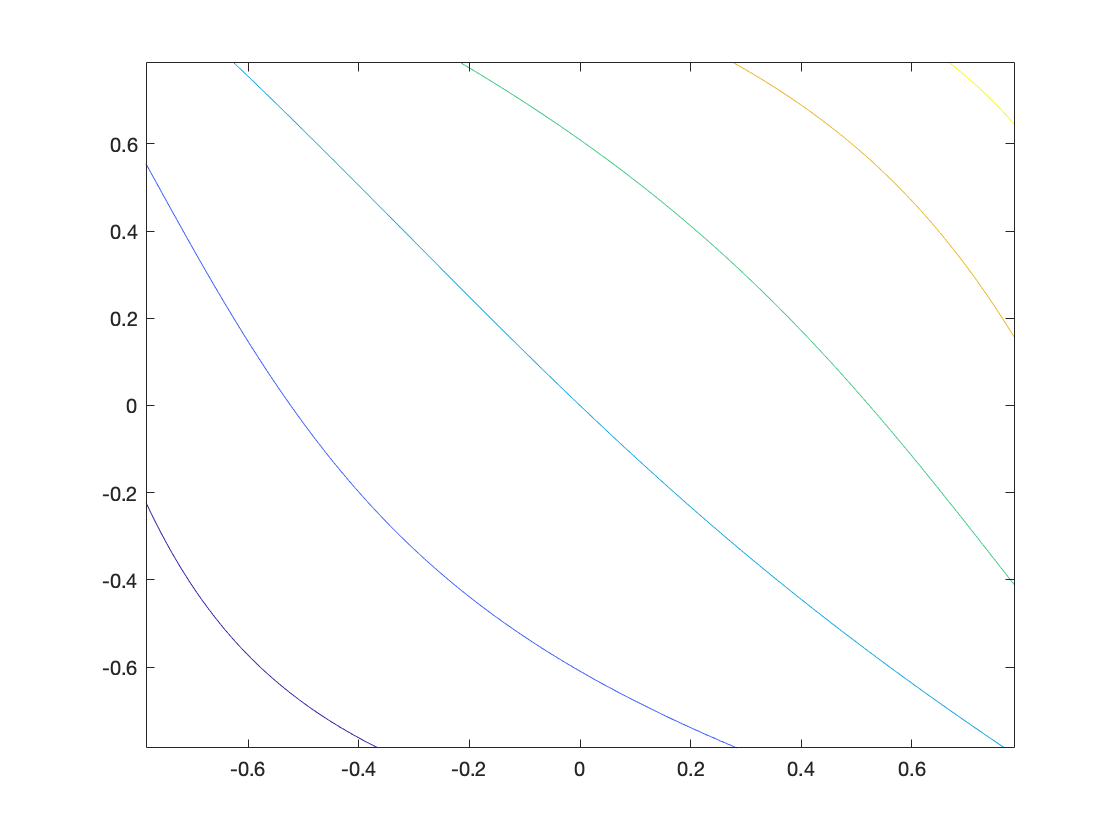

v = -1;
L_t = 2;
L_h = 0.5;
L_i = 1;
delta_ts = linspace(-pi/4,pi/4,100);
delta_is = linspace(-pi/4,pi/4,100);
phi = deg2rad(-30);

phi_dot_function = matlabFunction(subs(phi_dot),'Vars',[delta_t, delta_i]);
phi_dots = zeros(100);
for t = 1:100
    for i = 1:100
        phi_dots(t,i) = phi_dot_function(delta_ts(t), delta_is(i));
    end
end
contour(delta_ts, delta_is, phi_dots)

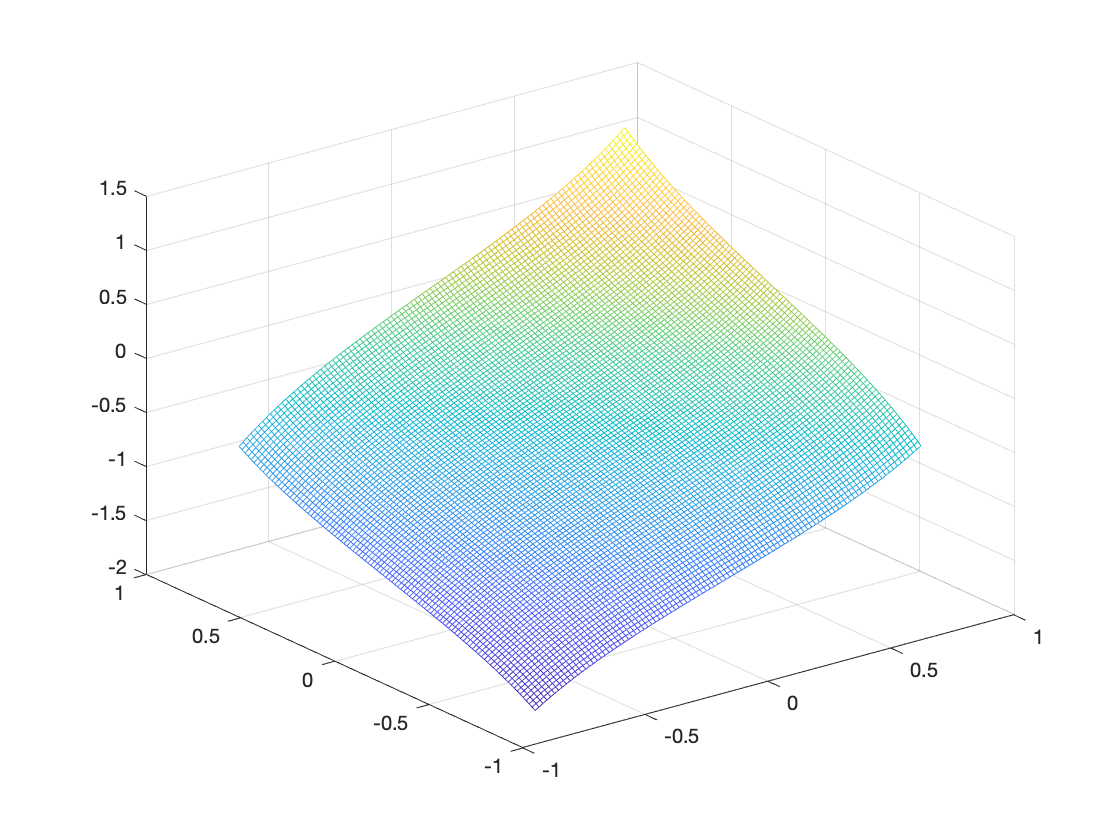

figure(2)
mesh(delta_ts, delta_is, phi_dots)